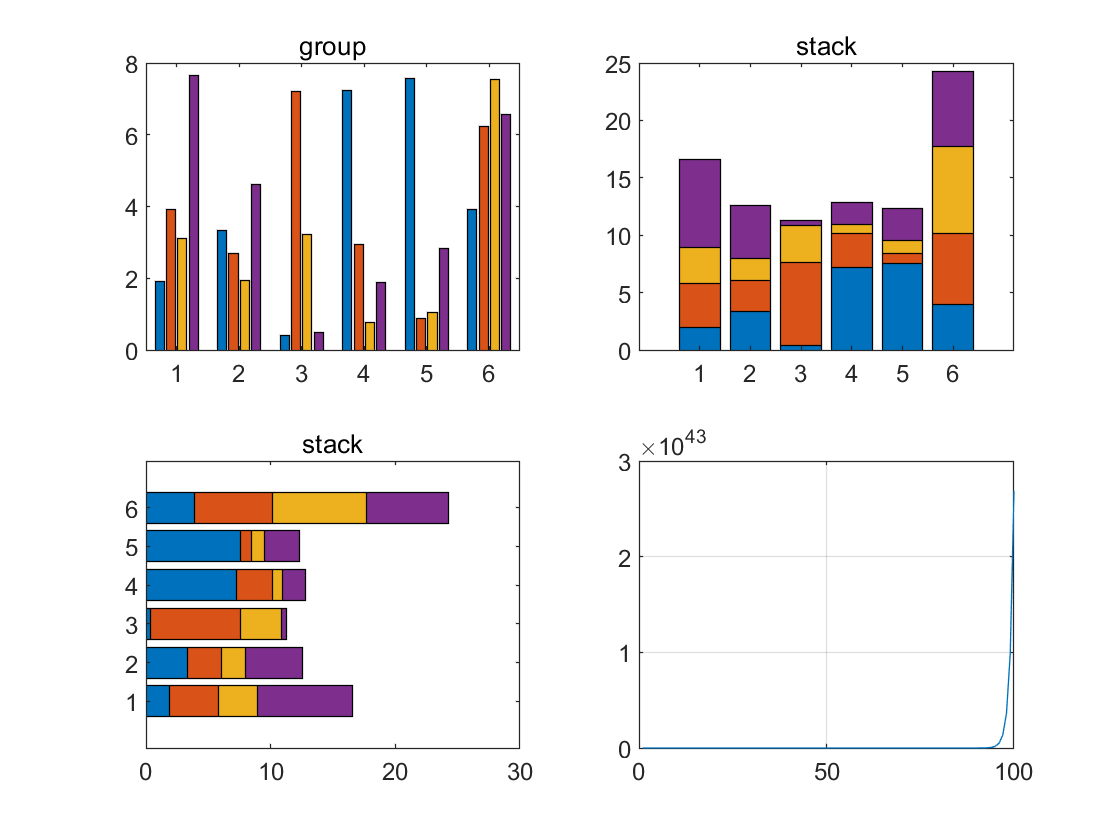

figure(1)
x=1:100;
y=exp(x);
%semilogy(x,y);
plot(x,y,'MarkerEdgeColor',[0.49 1  0.63]);
grid on 
hold on 
axis fill

%%-----------------------------------------画多轴二位图像-------------------------------
clc;clear;clf;
figure(2)
x=0:0.001:20;
y1=200*exp(-0.05*x).*sin(x);
y2=0.8*exp(-0.5*x).*sin(10*x);
[ax,h1,h2]=plotyy(x,y1,x,y2);       %绘制多轴标度图形
set(get(ax(1),'ylabel'),'string','慢衰减') %标注左侧纵坐标轴
set(get(ax(2),'ylabel'),'string','快衰减') %标注右侧纵坐标轴
xlabel('时间');
title('不同衰减速度对比');
grid on;
%ginput;
axis;


t=0:pi/100:2*pi;
plot(t,cos(2*t),':m.','LineWidth',1,'MarkerEdgeColor','g','MarkerFaceColor',['b'],'MarkerSize',1);
grid on
title('demo');
%gtext('312');

x=0:pi/50:pi;
y1=cos(2*x);y2=sin(x).*sin(6*x);
plot(x,y1,'r*',x,y2,'b- ');
%subplot(1,2,1),plot(x,y1,'r*');
%subplot(1,2,2),plot(x,y2,'b- ');
grid on
title('曲线y_1=cos(2x)和y_2=sin(x)sin(6x)');
xlabel('x轴');ylabel('y轴');
gtext('y_1=cos(2x)'),gtext('y_2=sin(x)sin(6x)');
legend('y_1=cos(2x)','y_2=sin(x)sin(6x)')

fplot('sin(x)',[-2*pi,2*pi])

syms t
ezplot(sin(t),[-2*pi,2*pi])

y=rand(6,4)*8

y =     2.9513    3.0102    1.8095    2.1222
    3.6858    1.5274    3.0770    6.5950
    7.8531    3.4260    4.6639    7.8613
    1.2512    3.8562    2.0144    5.8420
    6.8442    0.9649    2.3235    2.7510
    5.1581    4.7161    4.9367    4.6726


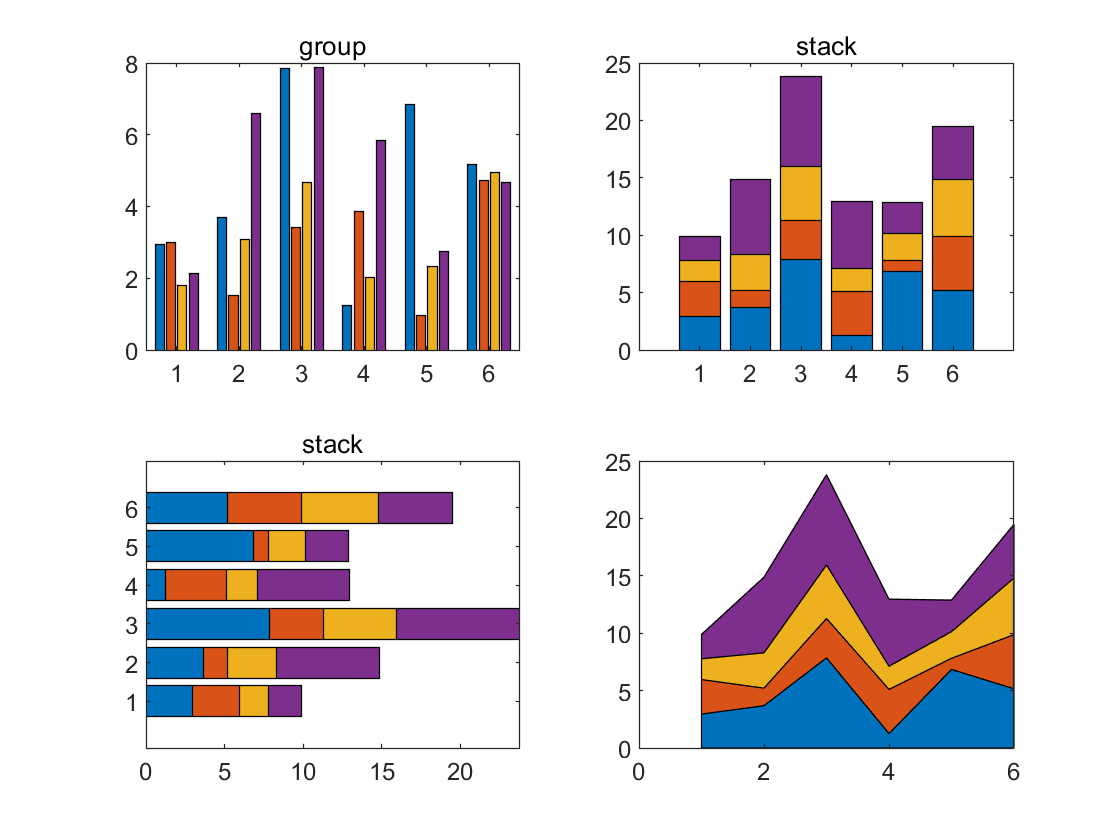

subplot(221),bar(y,'grouped'),title('group');
subplot(222),bar(y,'stacked'),title('stack');
subplot(223),barh(y,'stacked'),title('stack');
subplot(224),bar(y,1.6),title('group');
area(y)

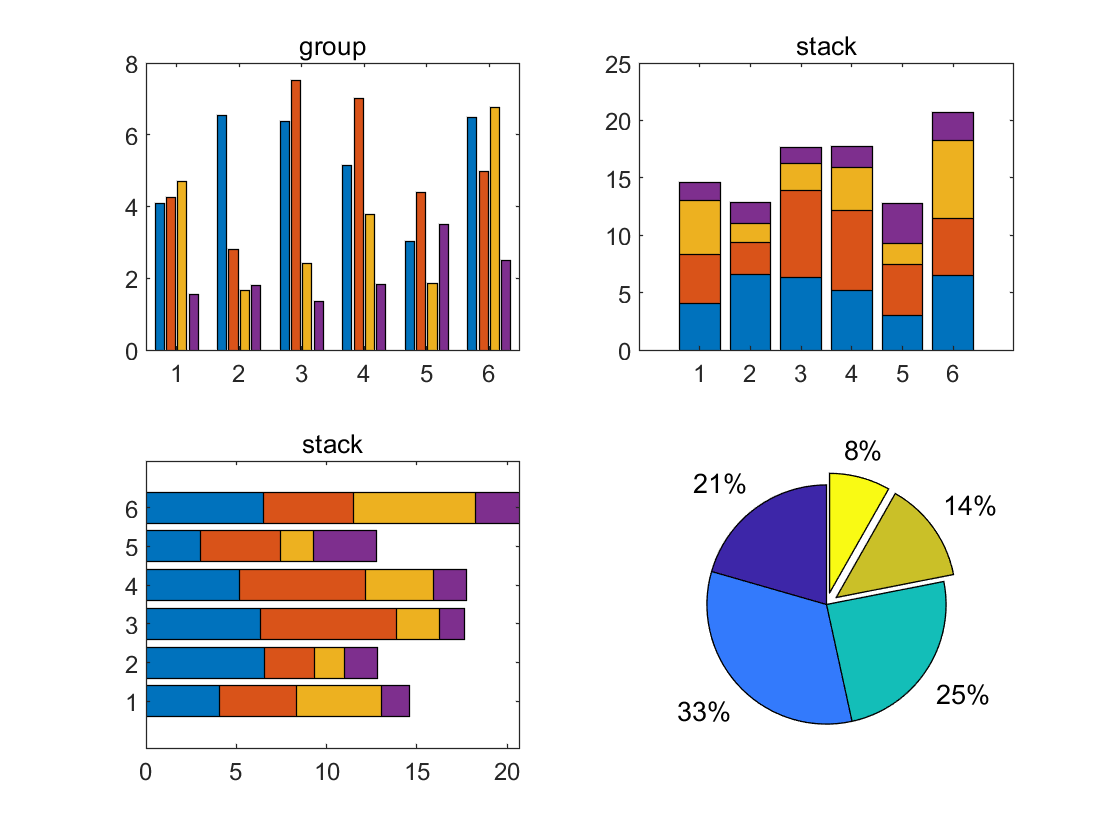


figure(2)
x=[30 48 36 20 12];
explode=[0 0 0 1 1];
pie(x,explode);


figure(4)
x=0:0.1:2

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


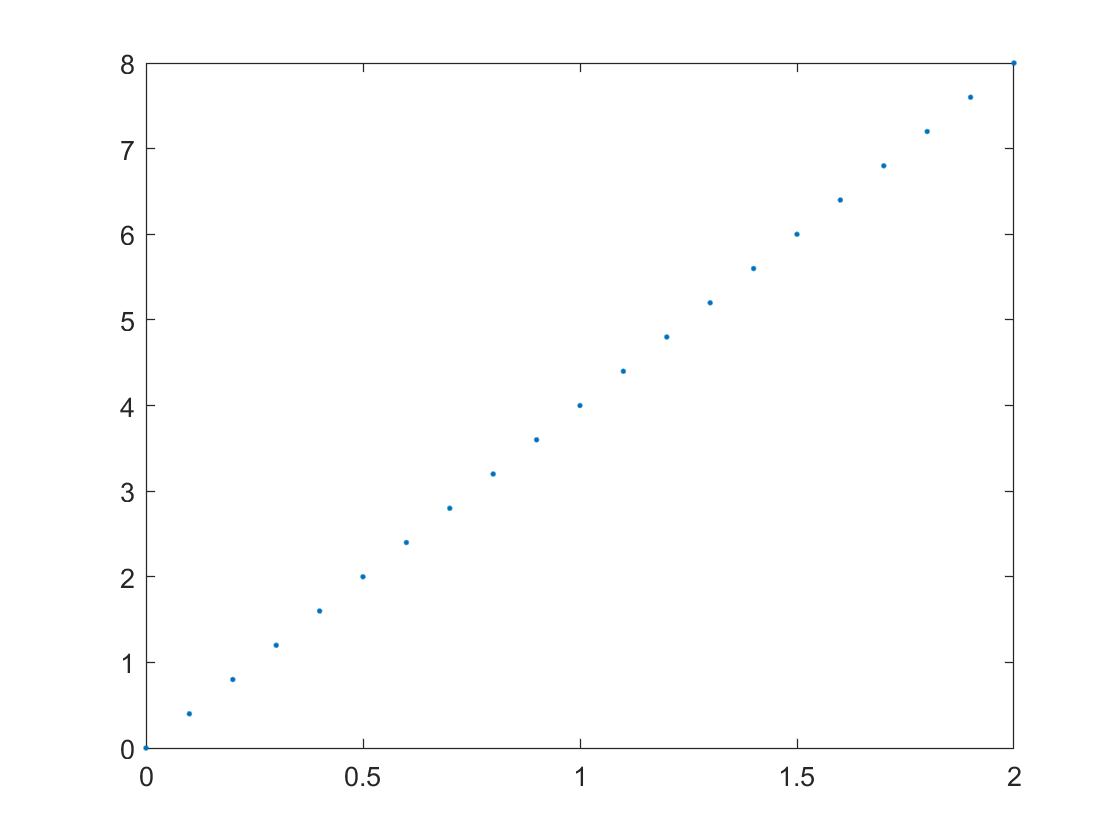

%stem(exp(-x.^2),'filled');
plot(x,x.*4,'.')